close all; clc; clearvars;
T_metadata = readtable('metadata.csv');
T_buenacalidad_revisadas = T_metadata(T_metadata.quality == 4, :)

T_buenacalidad_revisadas = 149×3 table
          image           glaucoma    quality
    __________________    ________    _______

    {'image_0009.jpg'}       0           4   
    {'image_0032.jpg'}       1           4   
    {'image_0048.jpg'}       0           4   
    {'image_0069.jpg'}       0           4   
    {'image_0078.jpg'}       0           4   
    {'image_0086.jpg'}       1           4   
    {'image_0094.jpg'}       0           4   
    {'image_0098.jpg'}       0           4   
    {'image_0128.jpg'}       1           4   
    {'image_0142.jpg'}       0           4   
    {'image_0175.jpg'}       0           4   
    {'image_0176.jpg'}       0           4   
    {'image_0206.jpg'}       0           4   
    {'image_0207.jpg'}       1           4   
    {'image_0208.jpg'}       0           4   
    {'image_0235.jpg'}       0           4   



[n, m] = size(T_buenacalidad_revisadas);
entropia = zeros(n,1);
rango_dinamico= zeros(n, 1);
std_intensidad= zeros(n, 1);
var_intensidad= zeros(n, 1);
CDR = zeros(n, 1);
DDLS = zeros(n, 1);

% i = 1;
for i=1:20
I = imread(T_buenacalidad_revisadas.image{i+40});
I_gray = rgb2gray(I);

I_borde = imbinarize(I_gray, 0.1);

% quitar los puntos blancos que aparecen fuera del ciruclo
% se = strel('disk', 15);
% I_borde = imerode(I_borde, se);
% 
% I = im2double(I);
% I(:, :, 1) = I(:, :, 1) .* I_borde;
% I(:, :, 2) = I(:, :, 2) .* I_borde;
% I(:, :, 3) = I(:, :, 3) .* I_borde;
% 
% I = im2uint8(I);

ROI con intensidad maxima (MEJOR)

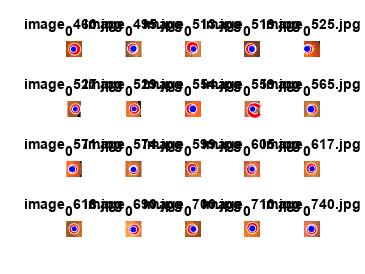

% OSCURECER BORDES 
se = strel('disk', 100); 
bordes = imerode(I_borde, se); 
I_gray_oscura = I_gray * 0;
I_gray_oscura(bordes) = I_gray(bordes);

I_gray_oscura = adapthisteq(I_gray_oscura);
% % Aplicar mapeo de intensidad (normalización)
% inpainted_image = imadjust(I_gray_oscura);
% 
% % Aplicar filtro Gaussiano para suavizar la imagen
gaussian_filtered_image = imgaussfilt(I_gray_oscura, 2);

I_gray_oscura = gaussian_filtered_image; 

% figure; subplot(121); imshow(I_gray);
% subplot(122); imshow(I_gray_oscura);

[max_fila, max_columna] = find(I_gray_oscura == max(I_gray_oscura(:)));
centroide_x = mean(max_fila);
centroide_y = mean(max_columna);

s = size(I_gray_oscura);
tamano_roi = min(s)/2;

inicio_x = max(1, round(centroide_x - tamano_roi/2));
fin_x = min(size(I_gray, 1), round(centroide_x + tamano_roi/2));
inicio_y = max(1, round(centroide_y - tamano_roi/2));
fin_y = min(size(I_gray, 2), round(centroide_y + tamano_roi/2));

roi = I(inicio_x:fin_x, inicio_y:fin_y, :);

% figure; imshow(roi); title(T_buenacalidad_revisadas.image{i});

red_channel = roi(:, :, 1);
green_channel = roi(:, :, 2);
blue_channel = roi(:, :, 3);
I_gray = rgb2gray(roi);

se = strel('disk', 30); 

canal_verde_sin_vasos = imclose(green_channel, se);
canal_rojo_sin_vasos = imclose(red_channel, se); %el canal rojo no tiene vasos
canal_azul_sin_vasos = imclose(blue_channel, se);
gray_sin_vasos = imclose (I_gray, se);

gray_sin_vasos1 = adapthisteq(gray_sin_vasos);
canal_azul_sin_vasos1 = adapthisteq(canal_azul_sin_vasos);
canal_verde_sin_vasos1 = adapthisteq(canal_verde_sin_vasos);
canal_rojo_sin_vasos1 = adapthisteq(canal_rojo_sin_vasos);

gray_sin_vasos2 = histeq(gray_sin_vasos);
canal_azul_sin_vasos2 = histeq(canal_azul_sin_vasos);
canal_verde_sin_vasos2 = histeq(canal_verde_sin_vasos);
canal_rojo_sin_vasos2 = histeq(canal_rojo_sin_vasos);

gray_sin_vasos3 = imadjust(gray_sin_vasos);
canal_azul_sin_vasos3 = imadjust(canal_azul_sin_vasos);
canal_verde_sin_vasos3 = imadjust(canal_verde_sin_vasos);
canal_rojo_sin_vasos3 = imadjust(canal_rojo_sin_vasos);

% figure; subplot(3,4,1); imshow(gray_sin_vasos1);
% subplot(3,4,2); imshow(canal_azul_sin_vasos1);
% subplot(3,4,3); imshow(canal_verde_sin_vasos1);
% subplot(3,4,4); imshow(canal_rojo_sin_vasos1);
% subplot(3,4,5); imshow(gray_sin_vasos2);
% subplot(3,4,6); imshow(canal_azul_sin_vasos2);
% subplot(3,4,7); imshow(canal_verde_sin_vasos2);
% subplot(3,4,8); imshow(canal_rojo_sin_vasos2);
% subplot(3,4,9); imshow(gray_sin_vasos3);
% subplot(3,4,10); imshow(canal_azul_sin_vasos3);
% subplot(3,4,11); imshow(canal_verde_sin_vasos3);
% subplot(3,4,12); imshow(canal_rojo_sin_vasos3);

e_gris = entropy(I_gray);
e_rojo = entropy(red_channel); % si es mas de 6 bien
e_verde = entropy(green_channel);
e_azul = entropy(blue_channel); % si es menos de 4 -> no usar %a partir de 6 no usar

e_gris1 = entropy(gray_sin_vasos1);
e_rojo1 = entropy(canal_rojo_sin_vasos1); 
e_verde1 = entropy(canal_verde_sin_vasos1);
e_azul1 = entropy(canal_azul_sin_vasos1);

e_gris2 = entropy(gray_sin_vasos2);
e_rojo2 = entropy(canal_rojo_sin_vasos2); 
e_verde2 = entropy(canal_verde_sin_vasos2);
e_azul2 = entropy(canal_azul_sin_vasos2);

if e_gris1 > 5 
    cup_threshold = 0.85 * max(gray_sin_vasos1(:)); % Umbral para la copa (brillo)
    
    cup_binary = gray_sin_vasos1 > cup_threshold; % Segmentación de la copa
else 
    cup_binary = ones(size(gray_sin_vasos));
end

if e_gris2 > 6
    disc_threshold = 0.9 * max(gray_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    disc_binary = gray_sin_vasos2 > disc_threshold; % Segmentación del disco completo
else 
    disc_binary = ones(size(gray_sin_vasos));
end

if e_rojo2 > 6
    disc_thresholdR = 0.95 * max(canal_rojo_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    disc_binaryR = canal_rojo_sin_vasos2 > disc_thresholdR; % Segmentación del disco completo
else 
    disc_binaryR = ones(size(gray_sin_vasos));
end

if e_verde2 > 5
    disc_thresholdG = 0.9 * max(canal_verde_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)
    
    disc_binaryG = canal_verde_sin_vasos2 > disc_thresholdG; % Segmentación del disco completo
else 
    disc_binaryG = ones(size(gray_sin_vasos));
end
 
if e_verde1 > 4.5 
    cup_thresholdG = 0.9 * max(canal_verde_sin_vasos1(:)); % Umbral para la copa (brillo)
  
    cup_binaryG = canal_verde_sin_vasos1 > cup_thresholdG; % Segmentación de la copa
else 
    cup_binaryG = ones(size(gray_sin_vasos));
end

if e_azul1 > 5.5 
    cup_thresholdB = 0.8 * max(canal_azul_sin_vasos1(:)); % Umbral para la copa (brillo)

    cup_binaryB = canal_azul_sin_vasos1 > cup_thresholdB; % Segmentación de la copa
else 
    cup_binaryB = ones(size(gray_sin_vasos));
end

if e_azul2 > 4
    disc_thresholdB = 0.9 * max(canal_azul_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)
    
    disc_binaryB = canal_azul_sin_vasos2 > disc_thresholdB; % Segmentación del disco completo
else 
    disc_binaryB = ones(size(gray_sin_vasos));
end

% Operación lógica de intersección para la segmentación de la copa
cup_binary_comun = cup_binary & cup_binaryG & cup_binaryB;

se = strel('disk', 5);
disc_binaryR = imdilate(disc_binaryR, se);
% Operación lógica de intersección para la segmentación del disco
disc_binary_comun = disc_binary & disc_binaryR & disc_binaryG  & disc_binaryB;

% figure; subplot(1,2,1); imshow(disc_binary_comun);
% subplot(1,2,2); imshow(cup_binary_comun);

se = strel('disk', 15);
disco = imerode(disc_binary_comun, se);
disco = bwareafilt(disco, 1);
disco = imdilate(disco, se);
copa = bwareafilt(cup_binary_comun, 1);
copa = imdilate(copa, se);

[fila, columna] = find(disco == max(disco(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_disco = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_disco = max(ancho_maximo, alto_maximo) / 2;

[fila, columna] = find(copa == max(copa(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_copa = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_copa = max(ancho_maximo, alto_maximo) / 2;

% figure; imshow(roi); title('Copa y disco')
subplot(4,5,i); imshow(roi); title(T_buenacalidad_revisadas.image{i+40});
hold on;
viscircles(centro_disco, radio_disco, 'EdgeColor', 'r', 'LineWidth', 2);
viscircles(centro_copa, radio_copa, 'EdgeColor', 'b', 'LineWidth', 2);
end

close all; clc; clearvars;
T_metadata = readtable('metadata.csv');
T_buenacalidad_revisadas = T_metadata(T_metadata.quality == 4, :);

i = 1;
% for i=1:20
I = imread('image_1430.jpg');
I_gray = rgb2gray(I);

% I_gray = I(:, :, 2);

% T = graythresh(I_gray); %0.3, 0.21
I_borde = imbinarize(I_gray, 0.1);

% quitar los puntos blancos que aparecen fuera del ciruclo
% se = strel('disk', 15);
% I_borde = imerode(I_borde, se);
% 
% I = im2double(I);
% I(:, :, 1) = I(:, :, 1) .* I_borde;
% I(:, :, 2) = I(:, :, 2) .* I_borde;
% I(:, :, 3) = I(:, :, 3) .* I_borde;
% 
% I = im2uint8(I);

ROI con intensidad maxima (MEJOR)

% OSCURECER BORDES 
se = strel('disk', 100); 
bordes = imerode(I_borde, se); 
I_gray_oscura = I_gray * 0;
I_gray_oscura(bordes) = I_gray(bordes);

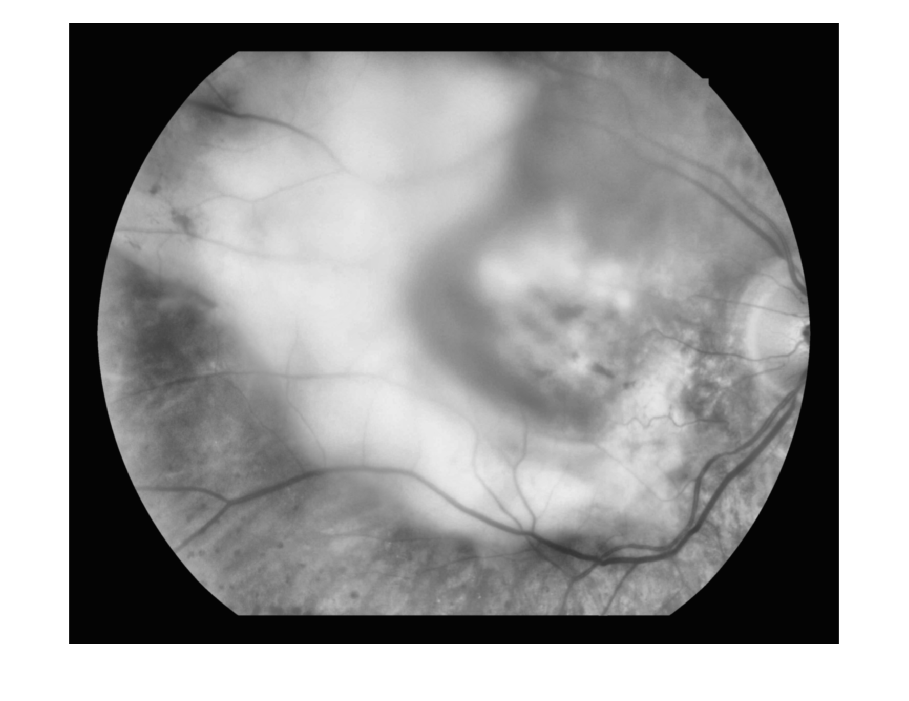

I_gray_oscura = adapthisteq(I_gray_oscura);
% % Aplicar mapeo de intensidad (normalización)
% % inpainted_image = imadjust(I_gray_oscura);
% figure; imshow(I_gray_oscura)
% Aplicar filtro Gaussiano para suavizar la imagen
gaussian_filtered_image = imgaussfilt(I_gray_oscura, 2);

I_gray_oscura = gaussian_filtered_image; 
figure; imshow(I_gray_oscura);

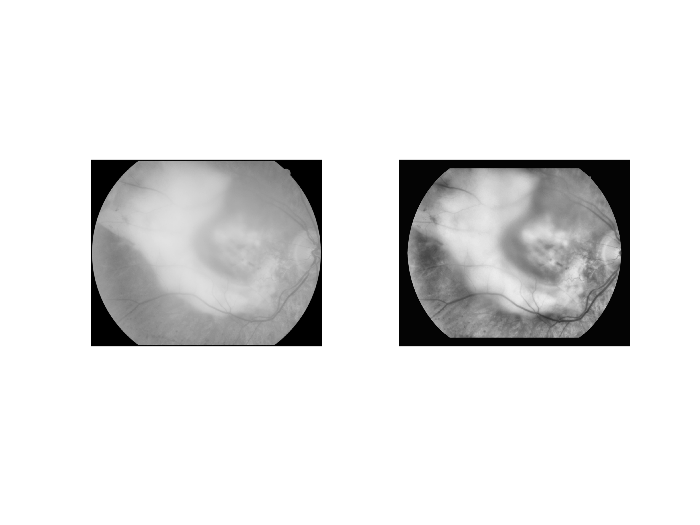

% I_gray_oscura = adapthisteq(I_gray_oscura);

figure; subplot(121); imshow(I_gray);
subplot(122); imshow(I_gray_oscura);

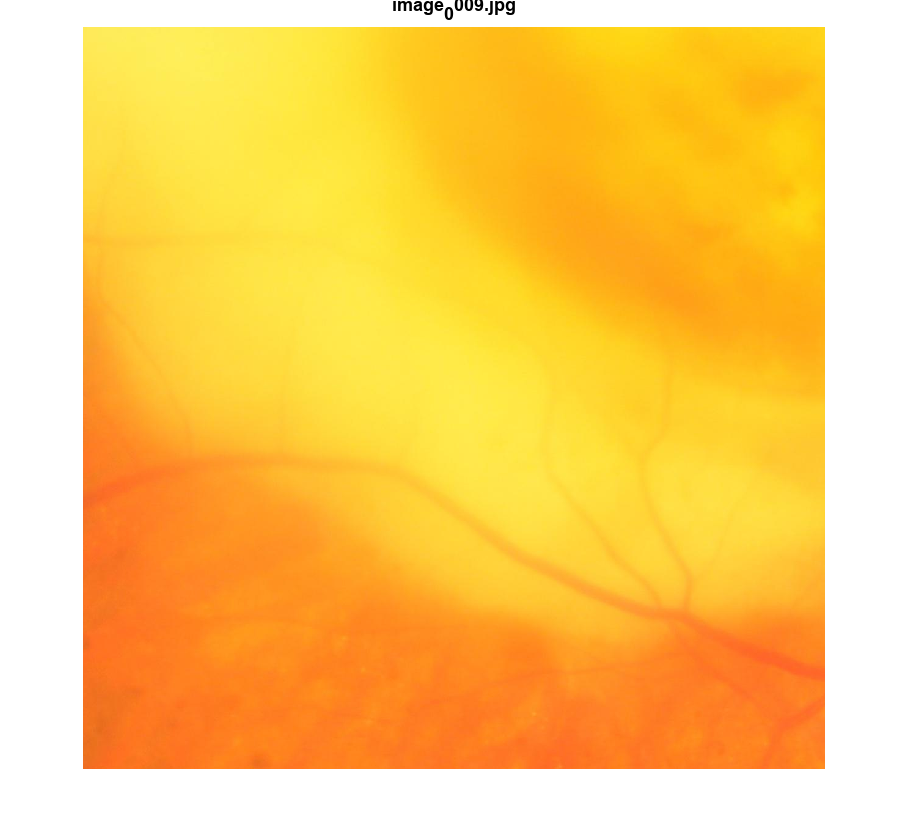


[max_fila, max_columna] = find(I_gray_oscura == max(I_gray_oscura(:)));
centroide_x = mean(max_fila);
centroide_y = mean(max_columna);

s = size(I_gray_oscura);
tamano_roi = min(s)/2;

inicio_x = max(1, round(centroide_x - tamano_roi/2));
fin_x = min(size(I_gray, 1), round(centroide_x + tamano_roi/2));
inicio_y = max(1, round(centroide_y - tamano_roi/2));
fin_y = min(size(I_gray, 2), round(centroide_y + tamano_roi/2));

roi = I(inicio_x:fin_x, inicio_y:fin_y, :);

figure; imshow(roi); title(T_buenacalidad_revisadas.image{i});

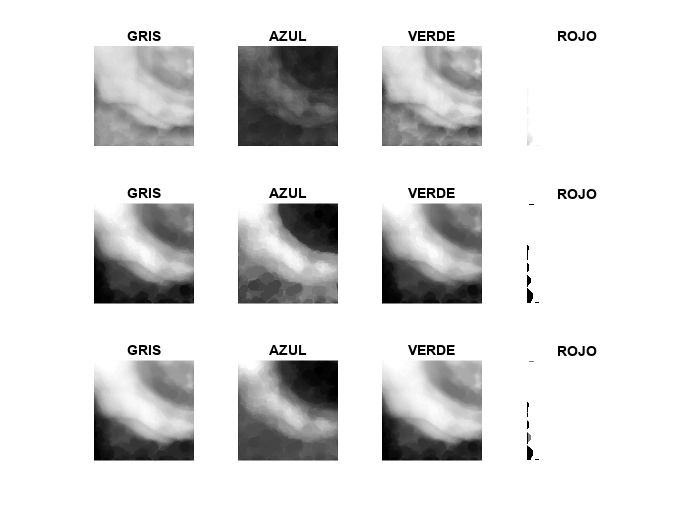


red_channel = roi(:, :, 1);
green_channel = roi(:, :, 2);
blue_channel = roi(:, :, 3);
I_gray = rgb2gray(roi);

se = strel('disk', 50); 

canal_verde_sin_vasos = imclose(green_channel, se);
canal_rojo_sin_vasos = imclose(red_channel, se); %el canal rojo no tiene vasos
canal_azul_sin_vasos = imclose(blue_channel, se);
gray_sin_vasos = imclose (I_gray, se);

gray_sin_vasos1 = adapthisteq(gray_sin_vasos);
canal_azul_sin_vasos1 = adapthisteq(canal_azul_sin_vasos);
canal_verde_sin_vasos1 = adapthisteq(canal_verde_sin_vasos);
canal_rojo_sin_vasos1 = adapthisteq(canal_rojo_sin_vasos);

gray_sin_vasos2 = histeq(gray_sin_vasos);
canal_azul_sin_vasos2 = histeq(canal_azul_sin_vasos);
canal_verde_sin_vasos2 = histeq(canal_verde_sin_vasos);
canal_rojo_sin_vasos2 = histeq(canal_rojo_sin_vasos);

gray_sin_vasos3 = imadjust(gray_sin_vasos);
canal_azul_sin_vasos3 = imadjust(canal_azul_sin_vasos);
canal_verde_sin_vasos3 = imadjust(canal_verde_sin_vasos);
canal_rojo_sin_vasos3 = imadjust(canal_rojo_sin_vasos);

figure; subplot(3,4,1); imshow(gray_sin_vasos1);  title('GRIS')
subplot(3,4,2); imshow(canal_azul_sin_vasos1); title('AZUL')
subplot(3,4,3); imshow(canal_verde_sin_vasos1); title('VERDE')
subplot(3,4,4); imshow(canal_rojo_sin_vasos1); title('ROJO')
subplot(3,4,5); imshow(gray_sin_vasos2);  title('GRIS')
subplot(3,4,6); imshow(canal_azul_sin_vasos2); title('AZUL')
subplot(3,4,7); imshow(canal_verde_sin_vasos2);title('VERDE')
subplot(3,4,8); imshow(canal_rojo_sin_vasos2);title('ROJO')
subplot(3,4,9); imshow(gray_sin_vasos3);title('GRIS')
subplot(3,4,10); imshow(canal_azul_sin_vasos3); title('AZUL')
subplot(3,4,11); imshow(canal_verde_sin_vasos3);title('VERDE')
subplot(3,4,12); imshow(canal_rojo_sin_vasos3);title('ROJO')

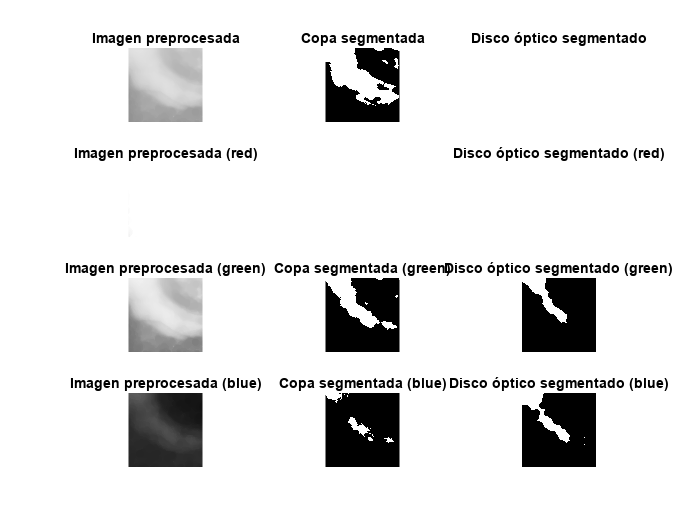


e_gris = entropy(I_gray);
e_rojo = entropy(red_channel); % si es mas de 6 bien
e_verde = entropy(green_channel);
e_azul = entropy(blue_channel); % si es menos de 4 -> no usar %a partir de 6 no usar

e_gris1 = entropy(gray_sin_vasos1);
e_rojo1 = entropy(canal_rojo_sin_vasos1); 
e_verde1 = entropy(canal_verde_sin_vasos1);
e_azul1 = entropy(canal_azul_sin_vasos1);

e_gris2 = entropy(gray_sin_vasos2);
e_rojo2 = entropy(canal_rojo_sin_vasos2); 
e_verde2 = entropy(canal_verde_sin_vasos2);
e_azul2 = entropy(canal_azul_sin_vasos2);

if e_gris1 > 5 
    cup_threshold = 0.85 * max(gray_sin_vasos1(:)); % Umbral para la copa (brillo)
    
    cup_binary = gray_sin_vasos1 > cup_threshold; % Segmentación de la copa
else 
    cup_binary = ones(size(gray_sin_vasos));
end

if e_gris2 > 6
    disc_threshold = 0.9 * max(gray_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    disc_binary = gray_sin_vasos2 > disc_threshold; % Segmentación del disco completo
else 
    disc_binary = ones(size(gray_sin_vasos));
end

if e_rojo2 > 6
    disc_thresholdR = 0.95 * max(canal_rojo_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    disc_binaryR = canal_rojo_sin_vasos2 > disc_thresholdR; % Segmentación del disco completo
else 
    disc_binaryR = ones(size(gray_sin_vasos));
end

if e_verde2 > 5
    disc_thresholdG = 0.9 * max(canal_verde_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)
    
    disc_binaryG = canal_verde_sin_vasos2 > disc_thresholdG; % Segmentación del disco completo
else 
    disc_binaryG = ones(size(gray_sin_vasos));
end
 
if e_verde1 > 4.5 
    cup_thresholdG = 0.9 * max(canal_verde_sin_vasos1(:)); % Umbral para la copa (brillo)
  
    cup_binaryG = canal_verde_sin_vasos1 > cup_thresholdG; % Segmentación de la copa
else 
    cup_binaryG = ones(size(gray_sin_vasos));
end

if e_azul1 > 5.5 
    cup_thresholdB = 0.8 * max(canal_azul_sin_vasos1(:)); % Umbral para la copa (brillo)

    cup_binaryB = canal_azul_sin_vasos1 > cup_thresholdB; % Segmentación de la copa
else 
    cup_binaryB = ones(size(gray_sin_vasos));
end

if e_azul2 > 4
    disc_thresholdB = 0.9 * max(canal_azul_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)
    
    disc_binaryB = canal_azul_sin_vasos2 > disc_thresholdB; % Segmentación del disco completo
else 
    disc_binaryB = ones(size(gray_sin_vasos));
end

figure; subplot(4, 3, 1); imshow(gray_sin_vasos); title('Imagen preprocesada');
subplot(4, 3, 2); imshow(cup_binary); title('Copa segmentada');
subplot(4, 3, 3); imshow(disc_binary); title('Disco óptico segmentado'); 
subplot(4, 3, 4); imshow(canal_rojo_sin_vasos); title('Imagen preprocesada (red)');
% subplot(4, 3, 5); imshow(cup_binaryR); title('Copa segmentada (red)');
subplot(4, 3, 6); imshow(disc_binaryR); title('Disco óptico segmentado (red)'); 
subplot(4, 3, 7); imshow(canal_verde_sin_vasos); title('Imagen preprocesada (green)');
subplot(4, 3, 8); imshow(cup_binaryG); title('Copa segmentada (green)');
subplot(4, 3, 9); imshow(disc_binaryG); title('Disco óptico segmentado (green)'); 
subplot(4, 3, 10); imshow(canal_azul_sin_vasos); title('Imagen preprocesada (blue)');
subplot(4, 3, 11); imshow(cup_binaryB); title('Copa segmentada (blue)');
subplot(4, 3, 12); imshow(disc_binaryB); title('Disco óptico segmentado (blue)'); 

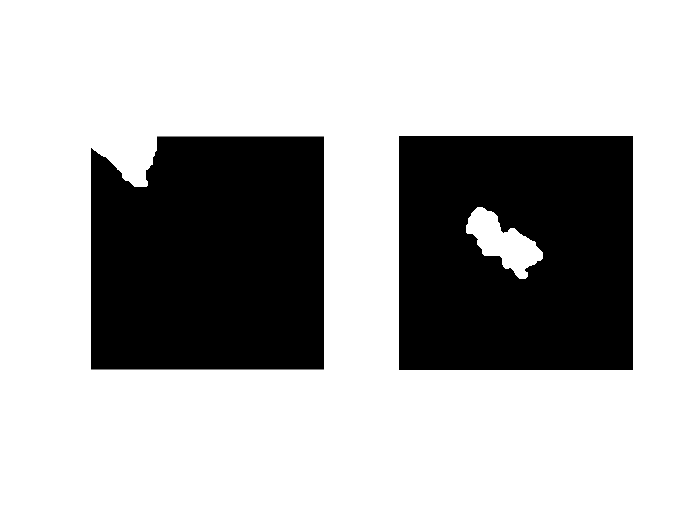


% Operación lógica de intersección para la segmentación de la copa
cup_binary_comun = cup_binary & cup_binaryG & cup_binaryB;

se = strel('disk', 10);
disc_binaryR = imdilate(disc_binaryR, se);
% Operación lógica de intersección para la segmentación del disco
disc_binary_comun = disc_binary & disc_binaryR & disc_binaryG  & disc_binaryB;

% figure; subplot(1,2,1); imshow(disc_binary_comun);
% subplot(1,2,2); imshow(cup_binary_comun);

se = strel('disk', 20);
disco = imerode(disc_binary_comun, se);
disco = bwareafilt(disco, 1);
disco = imdilate(disco, se);
copa = bwareafilt(cup_binary_comun, 1);
copa = imdilate(copa, se);

figure; subplot(1,2,1); imshow(disco);
subplot(1,2,2); imshow(copa);

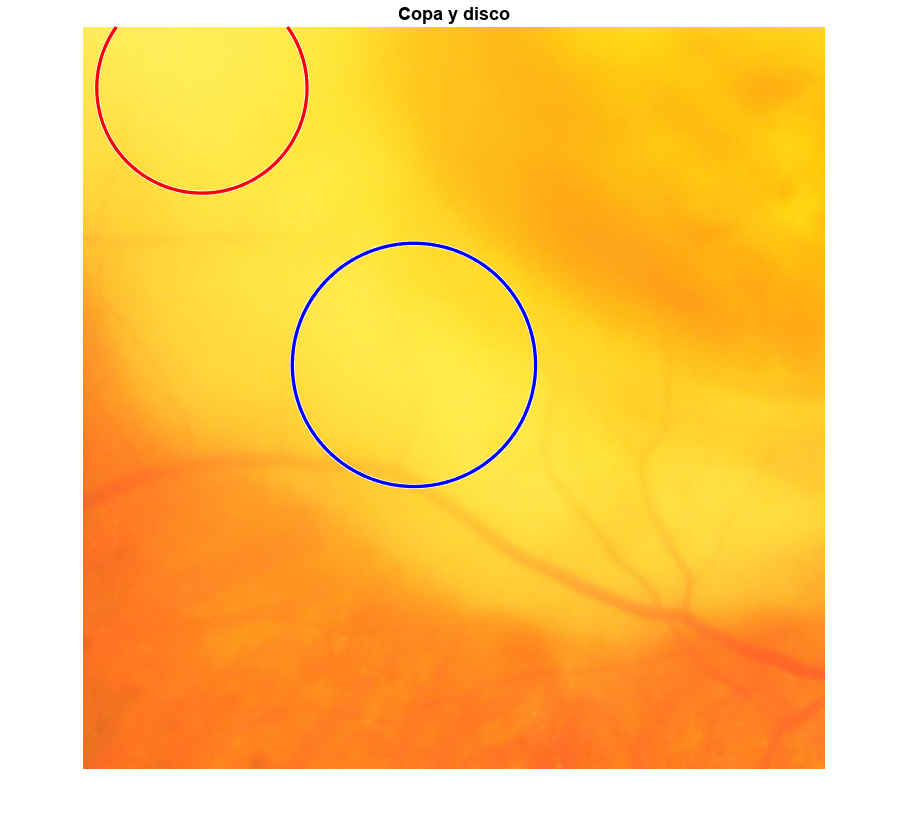


[fila, columna] = find(disco == max(disco(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_disco = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_disco = max(ancho_maximo, alto_maximo) / 2;

[fila, columna] = find(copa == max(copa(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_copa = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_copa = max(ancho_maximo, alto_maximo) / 2;

figure; imshow(roi); title('Copa y disco')
% subplot(4,5,i); imshow(roi); title(T_buenacalidad_revisadas.image{i});
hold on;
viscircles(centro_disco, radio_disco, 'EdgeColor', 'r', 'LineWidth', 2);
viscircles(centro_copa, radio_copa, 'EdgeColor', 'b', 'LineWidth', 2);